folder = fileparts(which('C:\Users\Sharon\OneDrive\Desktop\AnatArzi\eeglab2022.0\functions')); 
addpath(genpath(folder));

input_dir = 'C:\AnatArzData\Data\rerefrenced';
output_dir = 'C:\AnatArzData\YKM_data\epochs_and_evoked_allSubs\';
preproc_name = 'referenced';
sleep_files_name_suffix = strcat('_sleep_',preproc_name,'.set');
wake_files_name_suffix = strcat('_wake_night_',preproc_name,'.set');

subs = {'08','09','10','12','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

sleep_states_eeglab = {'N1','N2','N3','Rt','Rp'};
sleep_states = {'N1','N2','N3','REM'};
wake_states = {'Wn'};
vigilance_states_eeglab = [wake_states, sleep_states_eeglab];
vigilance_states = [wake_states, sleep_states];
TOA = {'T','O','A'};
electrodes = [5,6,11,80,85];
samples_per_epoch = 138;
toneHieghts = {'650','845','1098','1428','1856','2413','3137','4079','5302'};
trialnums = {'0','1','2','3','4','5','6','7','8','9'};
max_epochs_per_cond = 100;


% sub, vigilStage,electrodes, T/O/A, hieght , trialNum, #epochs ,evokedInTime
allSubsEvokeds = zeros( size(subs,2), size(vigilance_states,2), size(electrodes,2), size(TOA,2), ...
                        size(toneHieghts,2), size(trialnums,2), samples_per_epoch);

for sub_ind=1:size(subs,2)
    sub_epochs_filename = strcat(output_dir, 'epochs_sub',subs(sub_ind),'_', preproc_name, '_withElectorodes_test.mat');
    if isfile(sub_epochs_filename)
        string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  sub_epochs_filename))
        continue
    end
    currSubEpochs =   zeros( size(vigilance_states,2), size(electrodes,2),size(TOA,2), size(toneHieghts,2), ...
                            size(trialnums,2), max_epochs_per_cond, samples_per_epoch);
    
    isSleepData = 1; isWakeData = 1;
    %% get sub .set files loaded
    try
        eeglabsub_sleep =  pop_loadset(strcat('s_',subs(sub_ind),sleep_files_name_suffix), input_dir);
        subEvents_sleep = eeglabsub_sleep.event;
        subAllEpochs_sleep = eeglabsub_sleep.data;
        subAllEpochs_sleep = subAllEpochs_sleep(electrodes,:,:);
    catch ME
        isSleepData = 0;
    end
    
    try
        eeglabsub_wake =  pop_loadset( strcat('s_',subs(sub_ind),wake_files_name_suffix), input_dir);
        subEvents_wake = eeglabsub_wake.event;
        subAllEpochs_wake = eeglabsub_wake.data;
        subAllEpochs_wake = subAllEpochs_wake(electrodes,:,:); 
    catch ME
        isWakeData = 0;
    end
    
    if isSleepData + isWakeData <2
        strcat('Failed to find .set files of Sub',subs(sub_ind))
        continue
    end
    times = eeglabsub_wake.times;
    
    for vigil_ind=1:size(vigilance_states,2)
        for TOA_ind=1:size(TOA,2)
            for hieght_ind=1:size(toneHieghts,2)
                for trialnum_ind=1:size(trialnums,2)
                    
                    % get epochs numbers corresponding to a regex type of event 
                    currEventEpochsNums = [];
                    if strcmp(vigilance_states(vigil_ind),'REM')
                        currEvent_name = strcat('R[p,t]+',TOA(TOA_ind),toneHieghts(hieght_ind),'_', trialnums(trialnum_ind));
                        subEvents = subEvents_sleep;
                        subAllEpochs = subAllEpochs_sleep;
                    elseif strcmp(vigilance_states(vigil_ind),'Wn')
                        currEvent_name = strcat(TOA(TOA_ind),toneHieghts(hieght_ind),'_', trialnums(trialnum_ind));
                        subEvents = subEvents_wake;
                        subAllEpochs = subAllEpochs_wake;
                    elseif strcmp(vigilance_states(vigil_ind),'N1') || strcmp(vigilance_states(vigil_ind),'N2') || strcmp(vigilance_states(vigil_ind),'N3')
                        currEvent_name = strcat(sleep_states_eeglab(vigil_ind),TOA(TOA_ind),toneHieghts(hieght_ind),'_', trialnums(trialnum_ind));
                        subEvents = subEvents_sleep;
                        subAllEpochs = subAllEpochs_sleep;
                    else
                        strcat('Unknown vigi state ',vigilance_states(vigil_ind))
                        continue
                    end
                    currEvent_name = currEvent_name{1};
                    col_type = {subEvents.type};
                    col_epochNum = {subEvents.epoch};
                    for epoch=1:size(subEvents,2)
                        if regexp(col_type{epoch},currEvent_name) == 1
                            currEventEpochsNums = [currEventEpochsNums,[col_epochNum{epoch}]];
                        end
                    end
                   
                    % get subject's event's epochs mean 
                    currEventEpochs = subAllEpochs(:,:,currEventEpochsNums); 
                    
                    % populate evoked mat
                    mean_currEventEvokeds = mean(currEventEpochs,3); % mean over trials
                    allSubsEvokeds(sub_ind,vigil_ind,:,TOA_ind,hieght_ind,trialnum_ind,:) = mean_currEventEvokeds;
                    
                    % populate epochs mat
                    if size(currEventEpochs,3) == 1
                        currSubEpochs(vigil_ind,:,TOA_ind,hieght_ind,trialnum_ind,1,:) = currEventEpochs;
                    elseif size(currEventEpochs,3) > 1
                        currSubEpochs(vigil_ind,:,TOA_ind,hieght_ind,trialnum_ind,1:size(currEventEpochs,3),:) = permute(currEventEpochs,[1 3 2]);
                    end
                end
            end
        end
    end
    save(sub_epochs_filename{1}...
    ,"currSubEpochs","subs","sleep_states_eeglab","sleep_states","wake_states","vigilance_states_eeglab" ...
    ,"vigilance_states","times", "TOA","electrodes","samples_per_epoch","toneHieghts","trialnums");
end

pop_loadset(): loading file C:\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.set ...
Reading float file 'C:\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.fdt'...
Scaling components to RMS microvolt


pop_loadset(): loading file C:\AnatArzData\Data\rerefrenced\s_08_wake_night_referenced.set ...
Reading float file 'C:\AnatArzData\Data\rerefrenced\s_08_wake_night_referenced.fdt'...
Scaling components to RMS microvolt


## Look at individial trial

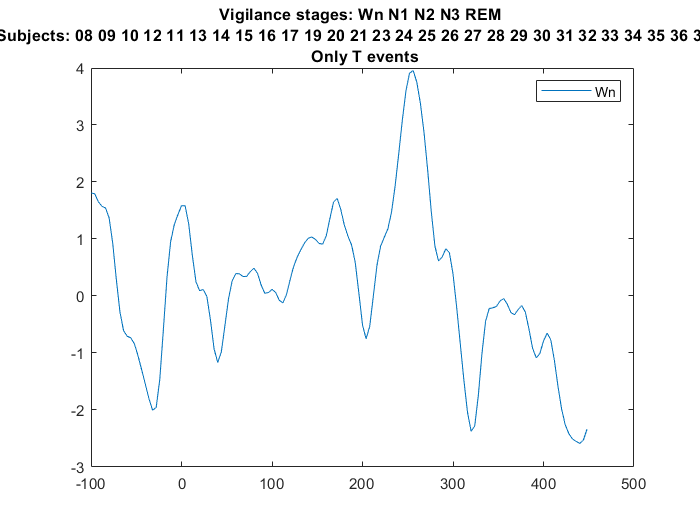

% sub, vigilStage, T/O/A, hieght , trialNum, #epochs ,evokedInTime

T_perVigiState = squeeze(allSubsEvokeds(1,1,:,1,1,1,:));
mean_T_perVigiState = squeeze(nanmean(T_perVigiState,[1]));
plot(eeglabsub_sleep.times,mean_T_perVigiState);
title(sprintf('Vigilance stages: %s \n Subjects: %s\n Only T events', strjoin(vigilance_states),strjoin(subs)));
legend(vigilance_states);

% mkdir(strcat(output_dir,output_name))
save(string(strcat(output_dir, 'evoked_', preproc_name, '_withElectorodes.mat'))...
    ,"allSubsEvokeds","subs","sleep_states_eeglab","sleep_states","wake_states","vigilance_states_eeglab" ...
    ,"vigilance_states","times", ...
    "TOA","electrodes","samples_per_epoch","toneHieghts","trialnums");